## CFD Assignment-1: Comparing different weighting functions for the weighted residual method

### Governing differential equation (GDE) and exact solutions

We have the parent ODE for the deflection of a beam with $M_0 $ as the bending moment at the supports and flexural rigdity $EI$ as given below: 


$$EI\frac{d^2y}{dx^2}-M_0=0 $$


Together with the boundary conditions: 


$$y(0)=y(L)=0$$


This gives us the exact solution as: 


$$y(x)=\frac{M_0}{2EI}(x^2-Lx) \$$


## Approximate solutions and the weighted residual statement

We shall now use two approximations to estimate the soltion to the GDE. The first is a second-order polynomial: 


$$u_1(x)=a_0+a_1x+a_2x^2
$$


And the second is a sinusoidal function as follows:


$$u_2(x)=A\sin(\frac{\pi x}{L})$$


The above function already satisfies the given BCs. Hence enforcing the boundary conditions onto the first trial function we get its modified forms as: 


$$u_1(x)=a_2(x^2-Lx)$$


Hence we compute the residual in each case as:


$$R_1=EI(2a_2-\frac{M_0}{EI})=R_1(a_2)$$



$$R_2=-M_0-(EI)(A)(\frac{\pi^2}{L^2})\sin(\frac{\pi x}{L})=R_2(A,x)$$


Note that we have the residual of the polynomial independant of $x$. We now use the weighted residual statement as follows using different trial functions $w$:


$$\int^L_0 R_i wdx=0$$


Where $i=1,2$ and the weighting functions take different values depending on the method we adopt. This is now presented one by one. 

#### The point collocation method

Here we choose the weighting function as the Dirac delta function:


$$w(x)=\delta(x-x_i)= 
\begin{cases}
    \infty,&x= x_i\\
    0,& x\neq x_i
\end{cases}$$


This function is also called the impulse function. Hence the weighted residual statement reduces to the following: 


$$R_{x=x_i}=0$$


In the case of the polynomial it doesn't matter as to what $x_i$ is as its independent of $x$. Hence we get the exact solution back. For the case of the sinusoidal function we have to choose an appropriate point. Say $x=L/2$. For this we get the following approximation: 


$$u_2(x)=-\frac {M_0L^2}{EI\pi^2}\sin(\frac{\pi x}{L})$$


The exact and the approximate solutions can be compared now. Let's use $MATLAB$ for this. For simplicity let $\frac{M_0}{EI}=1$ and $L=1$meter. We shall use a spacing of $0.1$meter along $x$. 

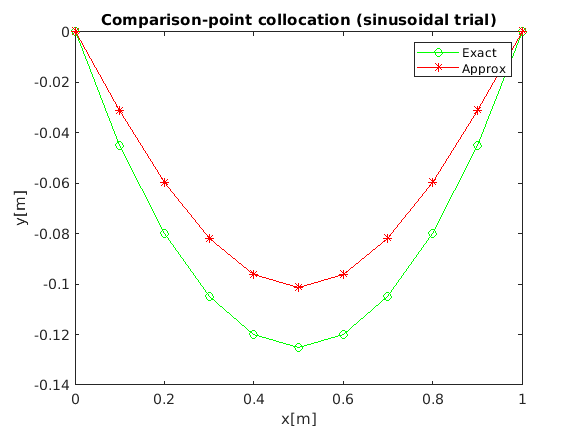

M0_by_EI=1;L=1; %declare the constants
X=[0:0.1:1]; %declare X vector 
Exact=(M0_by_EI*0.5)*(X.^2-L*X); %compute the exact solution
Approx_pc=-(M0_by_EI)*((L/pi)^2)*(sin(pi*X/L)); %compute approx solution
%visualize using plot
plot(X,Exact,'-og'); hold on;
plot(X,Approx_pc,'-*r');xlabel('x[m]');ylabel('y[m]');
legend('Exact','Approx'); title('Comparison-point collocation (sinusoidal trial)')
hold off;
hold off;

Let's compute the $%$$%age$$\%$ deviation using the following: 

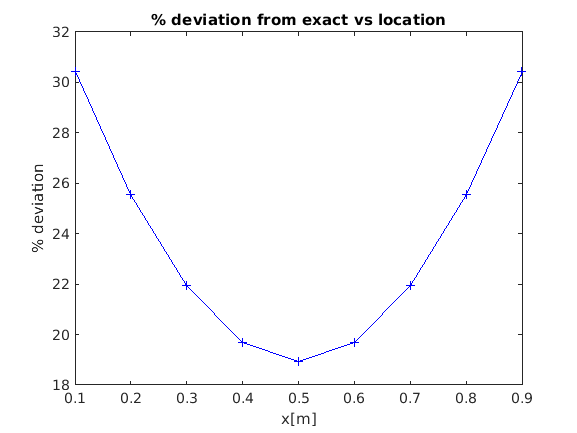

percent_dev=100*abs(Exact(2:end-1)-Approx_pc(2:end-1))./abs(Exact(2:end-1));
plot(X(2:end-1),percent_dev,'-+b');title('% deviation from exact vs location');xlabel('x[m]');
ylabel('% deviation')

#### The subdomain collocation method

Here we choose the weighting function as follows:


$$w(x)= 
\begin{cases}
    1,&x_i\leq x\leq x_j\\
    0,& otherwise
\end{cases}$$


Here $[x_i,x_j]$ is the subdomain over which the weight prevails. Hence the weighted residual statement reduces to the following: 


$$\int_{subdomain} Rdx=0$$


In the case of the polynomial it doesn't matter as to what $x_i$ is as its independent of $x$. Hence we get the exact solution back. For the case of the sinusoidal function we have to choose an appropriate subdomain. Say the entire domain. For this we get the following approximation: 


$$u_2(x)=-\frac {M_0L^2}{2EI\pi}\sin(\frac{\pi x}{L})$$


The exact and the approximate solutions can be compared now. 

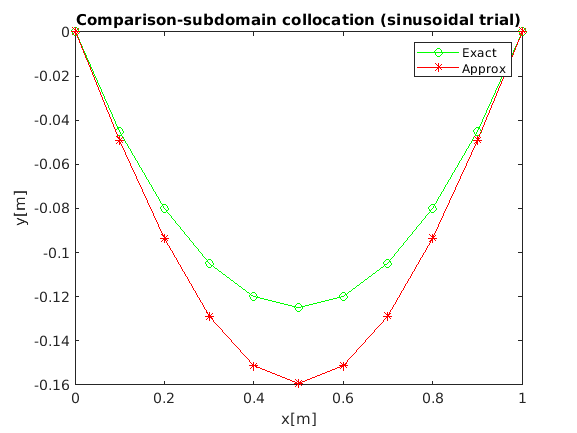

Approx_sc=-(M0_by_EI)*((L^2/2/pi))*(sin(pi*X/L)); %compute approx solution
%visualize using plot
plot(X,Exact,'-og'); hold on;
plot(X,Approx_sc,'-*r');xlabel('x[m]');ylabel('y[m]');
legend('Exact','Approx'); title('Comparison-subdomain collocation (sinusoidal trial)')
hold off;

Let's compute the $%$$%age$$\%$ deviation using the following: 

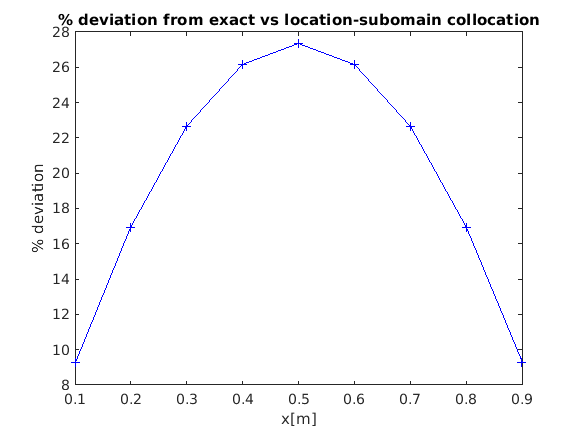

percent_dev=100*abs(Exact(2:end-1)-Approx_sc(2:end-1))./abs(Exact(2:end-1));
plot(X(2:end-1),percent_dev,'-+b');title('% deviation from exact vs location-subomain collocation');xlabel('x[m]');
ylabel('% deviation');

Note that the deviations are nearly half in this case compared to the earlier method. 

#### Galerkin's Method

Here the weight functions are chosen as the trial functions themselves. 


$$\int Rwdx=\int R_iu_idx$$


In the case of the polynomial doing this gives the exact solution back, yet again. For the case of the sinusoidal function repeating the above procedure with $R_2$ gives:


$$u_2(x)=-\frac {4M_0L^2}{EI\pi^3}\sin(\frac{\pi x}{L})$$


The exact and the approximate solutions can be compared now. 

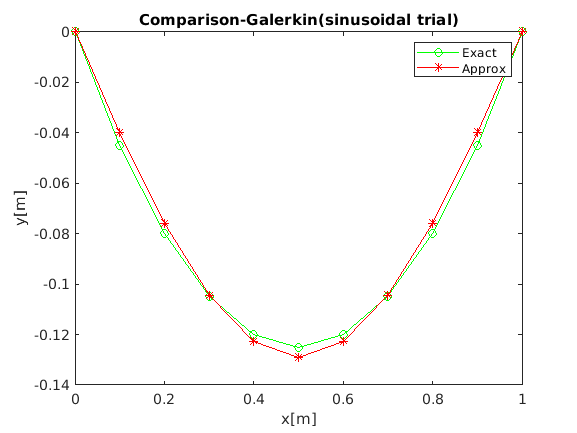

Approx_g=-(4*M0_by_EI)*((L^2/pi^3))*(sin(pi*X/L)); %compute approx solution
%visualize using plot
plot(X,Exact,'-og'); hold on;
plot(X,Approx_g,'-*r');xlabel('x[m]');ylabel('y[m]');
legend('Exact','Approx'); title('Comparison-Galerkin(sinusoidal trial)')
hold off;

Let's compute the $%$$%age$$\%$ deviation using the following: 

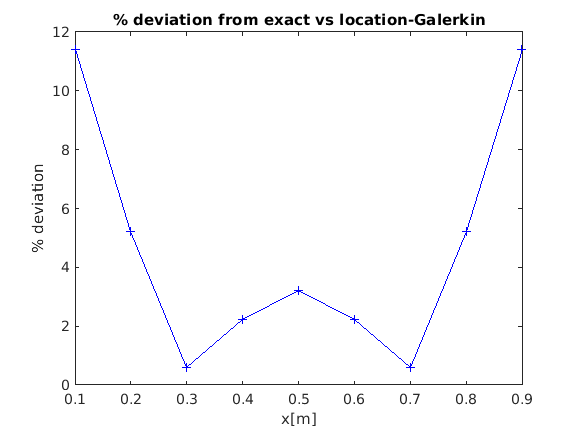

percent_dev=100*abs(Exact(2:end-1)-Approx_g(2:end-1))./abs(Exact(2:end-1));
plot(X(2:end-1),percent_dev,'-+b');title('% deviation from exact vs location-Galerkin');xlabel('x[m]');
ylabel('% deviation');

Note that the deviations are have decreased in this case compared to the earlier method. 

#### The Least Squares Method

Here the objective is to minimize the square of the residual:


$$minimize(\int R^2dx)$$


Let's do this for the polynomial trial function: 


$$minimize(\int R_1(a_2)^2dx)$$


Hence, we write accomplish this using: 


$$\frac{\partial}{\partial a_2}(\int R_1^2dx)=0$$


Taking the partial derivative inside we get: 


$$\int \frac{\partial}{\partial a_2}(R_1^2)dx=0$$


In the case of the polynomial doing this gives the exact solution back, yet again. For the case of the sinusoidal function repeating the above procedure with $A$ instead of $a_2$ gives:


$$u_2(x)=-\frac {4M_0L^2}{EI\pi^3}\sin(\frac{\pi x}{L})$$


The exact and the approximate solutions can be compared now. 

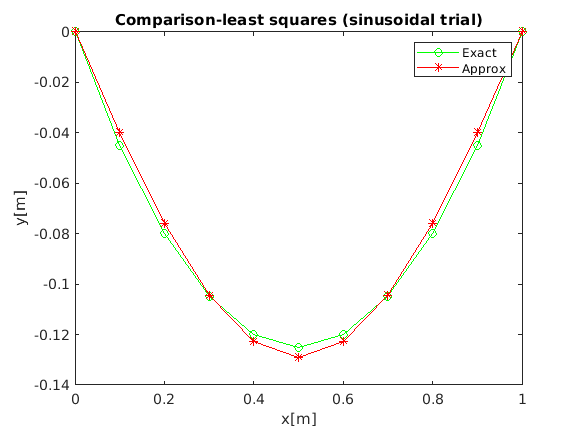

Approx_ls=-(4*M0_by_EI)*((L^2/pi^3))*(sin(pi*X/L)); %compute approx solution
%visualize using plot
plot(X,Exact,'-og'); hold on;
plot(X,Approx_ls,'-*r');xlabel('x[m]');ylabel('y[m]');
legend('Exact','Approx'); title('Comparison-least squares (sinusoidal trial)')
hold off;

Let's compute the $%$$%age$$\%$ deviation using the following: 

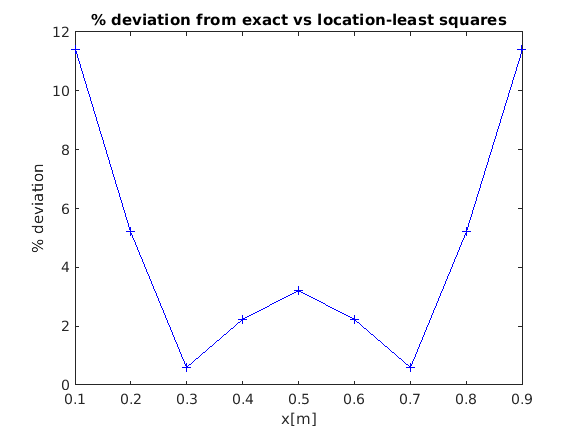

percent_dev=100*abs(Exact(2:end-1)-Approx_ls(2:end-1))./abs(Exact(2:end-1));
plot(X(2:end-1),percent_dev,'-+b');title('% deviation from exact vs location-least squares');xlabel('x[m]');
ylabel('% deviation');

Note that the deviations are have increased in this case compared to the earlier method. 

Let's now look at solutions from all the methods on a single graph to compare them easily.The following code does that:

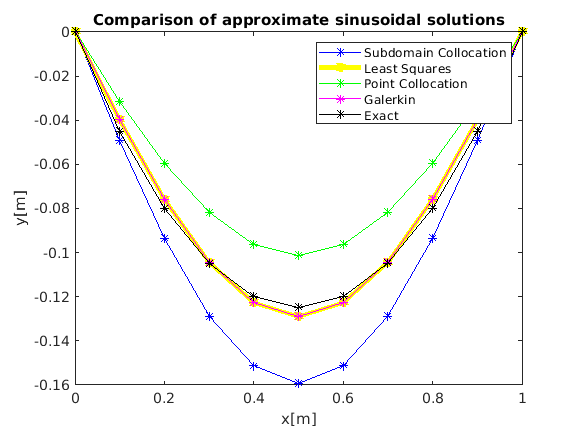

plot(X,Approx_sc,'-*b');hold on;
title('Comparison of approximate sinusoidal solutions');xlabel('x[m]');ylabel('y[m]');
plot(X,Approx_ls,'-*y','LineWidth',3);
plot(X,Approx_pc,'-*g');
plot(X,Approx_g,'-*m');
plot(X,Exact,'-*k');
legend('Subdomain Collocation','Least Squares','Point Collocation','Galerkin','Exact');
hold off;

Clearly, a single sinusoidal approximation doesn't always hold for this ODE! The polynomial solutions always hold, nonetheless as the original solution is also the same. This clearly shows the importance of the intial assumption and the method used to approximate solutions to ODEs.


$$done$$
 
$$by$$
 
$$-$$

$$R$$
 
$$Surya$$
 
$$Narayan$$
